# **Project 3 - How Infective Does a Disease Need to be for Masks to be Ineffective?**

**By Michaela Fox and Isabelle Rodriguez**

## **Question**

Our motivating question is how infective does a disease have to be for masks to no longer be effective? This is a design question because we are designing a model with the end goal of having masks not be effective in mind. We decided to choose this question because it would be useful to know when masks would no longer be effective against a disease and other preventive measures might be required. The people who would benefit from this answer are health officials responsible for spreading information and the general public who would want to know what is effective at preventing the spread of a disease. The background information that is necessary to understand this question and our modeling choices is the odds of getting infected when wearing different types of masks vs. no mask and how much of the population wears each type of mask or no mask.

Our literature search is as follows:

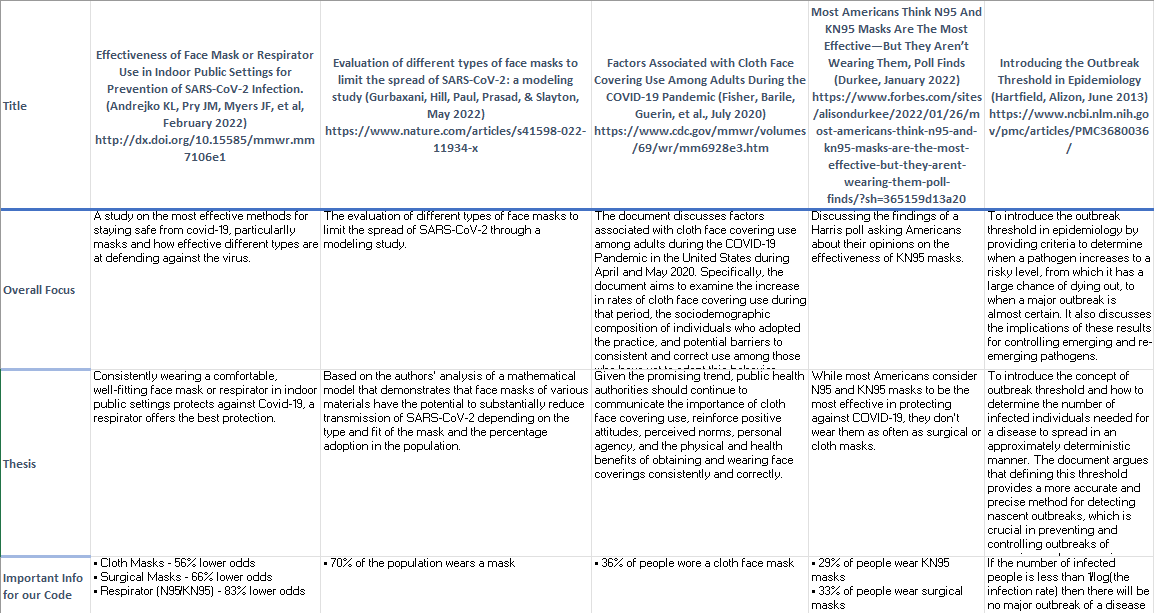

## Model

For our model we used an agent-based model with the transmission rate as our deterministic quantity and mask efficacy as our randomized quantity. To represent the probability that an individual would wear a certain type of mask we used a multinomial distribution as shown below: 

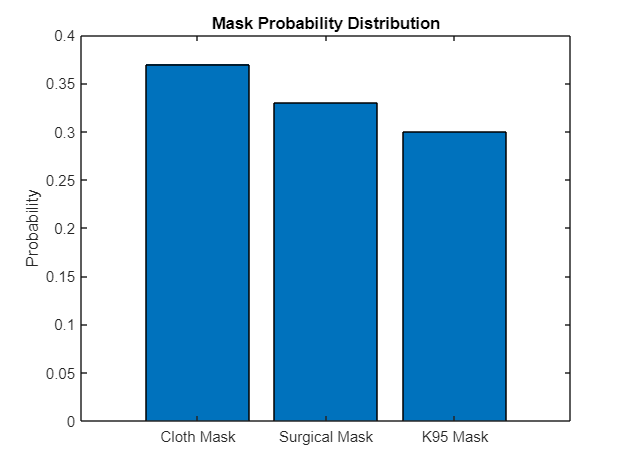

% mask efficacy
clothMaskEfficacy = .56;
surgicalMaskEfficacy = .66;
K95MaskEfficacy = .83;

% mask probability distribution (multinomial)
clothMaskProb = 0.37;
surgicalMaskProb = 0.33;
K95MaskProb = 0.3;
pd_mask_probabilities = makedist('Multinomial','Probabilities',[clothMaskProb surgicalMaskProb K95MaskProb]);

% Visualize
maskOutcomes = categorical({'Cloth Mask','Surgical Mask','K95 Mask'});
maskOutcomes = reordercats(maskOutcomes,{'Cloth Mask','Surgical Mask','K95 Mask'});
x = 1:3;
pr = pd_mask_probabilities.pdf(x);
figure();
bar(maskOutcomes, pr)
ylabel('Probability')
title('Mask Probability Distribution');

We then used simulate_absir() to find run 200 realizations of our model and then graphed the mean and upper and lower quantiles of the max infected with or without masks.

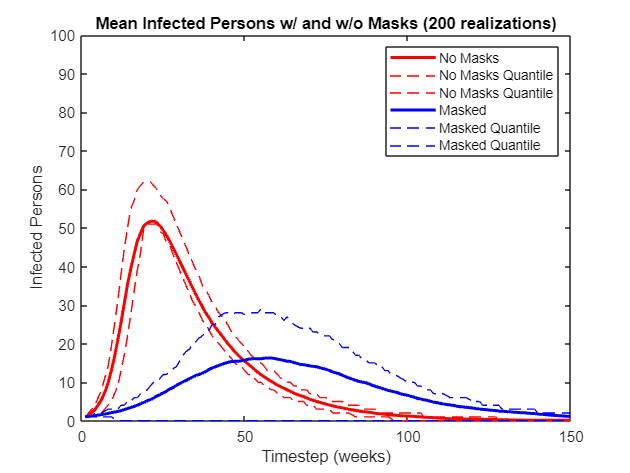

mask_matrix_random = random(pd_mask_probabilities, 100, 100);
mask_efficacy = [clothMaskEfficacy surgicalMaskEfficacy K95MaskEfficacy];
mask_matrix = mask_efficacy(mask_matrix_random); % converst from 1,2, and 3 to cloth, surgical, and K95 efficacy values (respectively)

% adjacency matrix 100 ppl
pop = 100;
no_mask_matrix = ~eye(pop,pop);

% Final Vulnerability Matrix
masked_vulnerability_matrix = no_mask_matrix - mask_matrix;
masked_vulnerability_matrix = masked_vulnerability_matrix.*-(eye(height(masked_vulnerability_matrix))-1);

% Simulate absir model w/ and w/o masks
    % Set the number of replications for the agent-based model
n_realizations = 200;
    % Run each simulation for 150 timesteps
T_simulation = 150;
    % Reserve space for simulation results
I_ensemble_no_mask = zeros(T_simulation, n_realizations);
I_ensemble_mask = zeros(T_simulation, n_realizations);
    % Set the random seed. 
%rng(101)
    % Set parameter values
infection_rate = 0.005;
recovery_rate = 0.05;

    % Generate the sample of results
for i = 1 : n_realizations
    % Run a single simulation
    Iv1 = zeros(pop, 1);
    Iv1(1) = 1;
    [Sh_mask, Ih_mask, Rh_mask] = simulate_absir(masked_vulnerability_matrix, Iv1, T_simulation, infection_rate, recovery_rate);
    % Check that the number of people stays at 100
    assert(sum(Sh_mask(:, end)) + sum(Ih_mask(:, end)) + sum(Rh_mask(:, end)) == pop, 'Number of people in masked realization went is not equal to the population')
    [Sh_no_mask, Ih_no_mask, Rh_no_mask] = simulate_absir(no_mask_matrix, Iv1, T_simulation, infection_rate, recovery_rate);
    % Check that the number of people stays at 100
    assert(sum(Sh_no_mask(:, end)) + sum(Ih_no_mask(:,end)) + sum(Rh_no_mask(:, end)) == pop, 'Number of people in no mask realization went is not equal to the population')
    % Summarize and store the infection history
    I_ensemble_mask(:, i) = sum(Ih_mask, 1);
    I_ensemble_no_mask(:, i) = sum(Ih_no_mask, 1);
end
% Check that everyone recovered
assert(sum(Ih_mask(:, end)) == 0, 'Not everyone recovered in the masked group')
assert(sum(Ih_no_mask(:,end)) == 0, 'Not everyone recovered in the no masked group')

    % Compute the mean and quantiles
    % Masked
I_mean_mask = mean(I_ensemble_mask, 2); % mean
I_lo_mask = quantile(I_ensemble_mask, 0.25, 2); % Lower (25%) quantile
I_up_mask = quantile(I_ensemble_mask, 0.75, 2); % Upper (75%) quantile
    % No mask
I_mean_no_mask = mean(I_ensemble_no_mask, 2);
I_lo_no_mask = quantile(I_ensemble_no_mask, 0.25, 2);
I_up_no_mask = quantile(I_ensemble_no_mask, 0.75, 2);

    % Visualize
figure()
% plot w/o masks
plot(I_mean_no_mask, 'r-', 'LineWidth', 2.0, 'DisplayName', 'No Masks'); hold on
plot(I_lo_no_mask, 'r--', 'LineWidth', .5, 'DisplayName', 'No Masks Quantile');
plot(I_up_no_mask, 'r--', 'LineWidth', .5, 'DisplayName', 'No Masks Quantile');
% plot w/ masks
plot(I_mean_mask, 'b-', 'LineWidth', 2.0, 'DisplayName', 'Masked'); 
plot(I_lo_mask, 'b--', 'LineWidth', .5, 'DisplayName', 'Masked Quantile');
plot(I_up_mask, 'b--', 'LineWidth', .5, 'DisplayName', 'Masked Quantile');hold off
xlabel('Timestep (weeks)')
ylabel('Infected Persons')
ylim([0 pop])
legend()
title('Mean Infected Persons w/ and w/o Masks (200 realizations)')

The assumptions we made when creating our model were that all cloth masks were made from the same type of cloth and that every person who was wearing a mask was wearing one properly. These are acceptable for our modeling question because most cloth masks that are known to protect against viruses have very similar effectivity rates, therefore making it redundant to include all of them, and if we assumed some people were not wearing masks properly it would be difficult to know if our results were caused by just the masks or through a mix of masks and human error. We set the parameters of our model based on a mix of our literature research and values from previous worksheets. The mask efficacies and probabilities were determined from our literature research, and the recovery and infection rates were taken from a previous worksheet. The infection rate was swept to determine the answer to our modeling question. The verification facts we came up with are making sure the total number of people stays at 100 and making sure that everyone recovers at some point.

## Results

The metric we used to help answer our question was the max number of infected people. This is an appropriate metric because if the max infected for both the population wearing masks and the population not wearing masks is the same that means that masks are ineffective and will answer our modeling question. The results we generated using our model were that a disease must have an infectivity rate of 0.0722 in order for masks to be completely ineffective.

% Set infectivity rate values to sweep
infectivity_all = linspace(.005, .1, 100);

% Store metric (mean infection peak)
mean_infection_peak_mask = zeros(1, 100);
mean_infection_peak_no_mask = zeros(1, 100);

% Reserve space for simulation results
I_ensemble_no_mask_sweep = zeros(T_simulation, n_realizations);
I_ensemble_mask_sweep = zeros(T_simulation, n_realizations);

% run simulation for each value of infectivity rate

    for i = 1 : length(infectivity_all)
        infectivity_rate = infectivity_all(i);

        % Run 100 simulations
        for j = 1:n_realizations
            Iv1 = zeros(pop, 1);
            Iv1(1) = 1;
            [Sh_mask, Ih_mask, Rh_mask] = simulate_absir(masked_vulnerability_matrix, Iv1, T_simulation, infectivity_rate, recovery_rate);
            [Sh_no_mask, Ih_no_mask, Rh_no_mask] = simulate_absir(no_mask_matrix, Iv1, T_simulation, infectivity_rate, recovery_rate);

            % Summarize and store the infection history
            I_ensemble_mask_sweep(:, j) = sum(Ih_mask, 1);
            I_ensemble_no_mask_sweep(:, j) = sum(Ih_no_mask, 1);
        end
        % Get mean
        I_mean_mask = mean(I_ensemble_mask_sweep, 2); % mask mean
        I_mean_no_mask = mean(I_ensemble_no_mask_sweep, 2); % no mask mean

        % Get mean peaks and store as metrics
        mean_infection_peak_mask(i) = max(I_mean_mask); % mask
        mean_infection_peak_no_mask(i) = max(I_mean_no_mask); % no mask
    end


% Determine infectivity value that causes masks to become ineffective based on determined threshold
percent_threshold = 0.2; % if the masked infection peak is within []% of the no mask peak, masks are ineffective

threshhold_check = zeros(1,100);
for i = 1:length(infectivity_all)
    diff_mask_no_mask = mean_infection_peak_no_mask(i) - mean_infection_peak_mask(i);
    if (diff_mask_no_mask <= percent_threshold * mean_infection_peak_no_mask) % checks if mask peak is within []% of no mask peak
        threshhold_check(i) = infectivity_all(i);
    end
end
threshhold_check % stores the infectivity rate for each value where masks are ineffective (if masks were effective there will be a zero)

threshhold_check =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0405    0.0415         0    0.0434         0    0.0453         0         0    0.0482    0.0491         0    0.0511    0.0520


point_of_ineffectiveness = threshhold_check(71) % infectivity rate where masks become ineffective

point_of_ineffectiveness = 0.0722

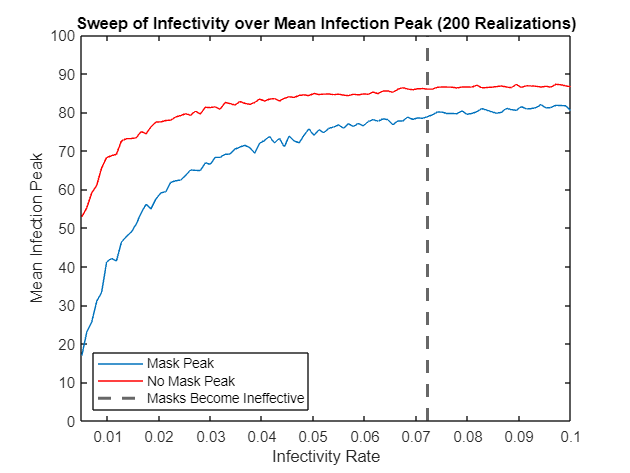

[mx,my] = polyxpoly(infectivity_all, mean_infection_peak_mask, infectivity_all, mean_infection_peak_no_mask);
% Plot results
plot(infectivity_all, mean_infection_peak_mask, 'DisplayName', 'Mask Peak'); hold on % mask
plot(mx,my,'g.', 'MarkerSize', 15, 'DisplayName', 'Masks not effective');
xline(point_of_ineffectiveness, 'LineWidth', 2, 'LineStyle', '--', 'DisplayName', 'Masks Become Ineffective') % point where masks become ineffective
plot(infectivity_all,mean_infection_peak_no_mask, 'r', 'DisplayName', 'No Mask Peak'); hold off % no mask
xlabel('Infectivity Rate')
ylabel('Mean Infection Peak')
title('Sweep of Infectivity over Mean Infection Peak (200 Realizations)')
legend('Location','southwest')
ylim([0 100])
xlim([infectivity_all(1) infectivity_all(end)])

The most important trends in our parameter sweep are that both the masked and no masked graphs increase exponentially, with the difference in the mean max infected between them decreasing as they both increased.

## Interpretation

Our parameter sweep answers our question of at what infectivity rate are masks no longer effective, which is 0.0722. Some limitations of our model are that it cannot account for any other circumstances which would make someone more or less immune to a disease. It also does not consider the differences in effectivity between the different cloths that can be used to make a cloth mask. If we were to continue to develop our model, we would add more mask types to take into account the different materials used to make cloth masks, we might also take into account that some people do not wear masks the right way.

## Validation

According to a 2013 study analyzing what qualifies as an outbreak, in order for the spread of a disease to qualify as an outbreak, at least 57% of people must be infected. According to our results, 75% of people were infected when masks were considered ineffective, meaning that even with everyone wearing masks, a disease with an infection rate of 0.0722 would still cause an outbreak. 